**1.NEWTON RAPHSON METHOD**

Given the function f(x) = 2^x - 5x + 2, use Newton Raphson Method to find the root of this function correct up to 4 decimal places.(e = 10^-4)

Requirements 

f = @ (x) 2^x - 5*x + 2; % Funtion
df = @ (x) log(2)*(2^x) - 5; %Derivative of function
e = 10^-4; % Tolerance
x0 = 0; % Initial guess
n = 10; % Number of iterations

Processing

tic;
if df (x0) ~=0
   for i=1:n
       x1 = x0 - f(x0)/df(x0) %Newton Raphson Formula
       fprintf('x%d = %.10f\n',i,x1)
       if abs(x1-x0)<e
           break
       end
       if df(x1)==0
           disp('Newton Raphson Failed')
       end
       x0 = x1;
   end   
else
    disp('Newton Raphson Failed');
end 

x1 = 0.6966

x1 = 0.6965643187


x1 = 0.7321

x2 = 0.7321153457


x1 = 0.7322

x3 = 0.7322442538


x1 = 0.7322

x4 = 0.7322442555


elapsedTime = toc;
fprintf('Computation time: %.6f seconds\n',elapsedTime);

Computation time: 0.027102 seconds


**2.BISECTION METHOD**

Given the function f(x) = 2^x - 5x + 2, use Bisection Method to find the root of this function correct up to 4 decimal places.(e = 10^-4)

Requirements

f = @ (x) 2^x - 5*x + 2;  % Function
a = 0;  %Leftside of interval 
b = 1;  %Rightside of the interval
n = 30;  %Number of iterations
e = 10^-4;  %Tolerance
tic;
if f(a)*f(b)<0
    for i=1:n
        c = (a+b)/2;   %Bisecion method formula
        if abs(c-b)<e || abs(c-a)<e
            break
        end
        fprintf('P%d = %.4f\n',i,c)
        if f(a)*f(c)<0
            b = c;
        elseif f(b)*f(c)<0
            a = c;
        end
    end

else
    disp('No root between given brackets')
end

P1 = 0.5000
P2 = 0.7500
P3 = 0.6250
P4 = 0.6875
P5 = 0.7188
P6 = 0.7344
P7 = 0.7266
P8 = 0.7305
P9 = 0.7324
P10 = 0.7314
P11 = 0.7319
P12 = 0.7322
P13 = 0.7323


elapsedTime = toc;
fprintf('Computation time: %.6f seconds\n',elapsedTime);

Computation time: 0.136205 seconds


**3.SECANT METHOD**

Given the function f(x) = 2^x - 5x + 2, use Secant Method to find the root of this function correct up to 4 decimal places.(e = 10^-4)

Requirements

f = @ (x) 2^x - 5*x + 2;  % Function
x0 = 0; %Initial first guess
x1 = 1; %Second initial guess
e = 10^-4; %Tolerance
n = 10; %Number of iterations

Processing

tic;
for i=1:n
    x2 = ((x0)*f(x1)-x1*f(x0))/(f(x1)-f(x0))  % Secant Method Formula
    fprintf('x%d = %.4f\n',i,x2)
    if abs(x2-x1)<e
        break
    end
    x0 = x1;
    x1 = x2;
end

x2 = 0.7500

x1 = 0.7500


x2 = 0.7317

x2 = 0.7317


x2 = 0.7322

x3 = 0.7322


x2 = 0.7322

x4 = 0.7322


elapsedTime = toc;
fprintf('Computation time: %.6f seconds\n',elapsedTime);

Computation time: 0.032729 seconds


**4.FIXED POINT ITERATION METHOD**

Given the function f(x) = 2^x - 5x + 2, use Fixed Point Iteration Method to find the root of this function correct up to 4 decimal places.(e = 10^-4). Use x0 = 0 as initial guess.

Requirements

g = @(x)(2^x+2)/5';
x0 = 0;
e = 10^-4;
n = 20;

Processing

tic;
for i=1:n
    x1 = g(x0)
    fprintf('x%d = %.4f\n',i,x1)
    if abs(x1-x0)<e
        break
    end
    x0 =x1;
end

x1 = 0.6000

x1 = 0.6000


x1 = 0.7031

x2 = 0.7031


x1 = 0.7256

x3 = 0.7256


x1 = 0.7307

x4 = 0.7307


x1 = 0.7319

x5 = 0.7319


x1 = 0.7322

x6 = 0.7322


x1 = 0.7322

x7 = 0.7322


elapsedTime = toc;
fprintf('Computation time: %.6f seconds\n',elapsedTime);

Computation time: 0.049905 seconds


**5. CRAMER'S RULE**

Solve the following system of linear equations using Cramer's Rule

10x1 + 3x2 + x3 = 19

3x1 + 10x2 + 2x3 = 29

x1 + 2x2 + 10x3 = 35

A = [10 3 1;3 10 2;1 2 10]   % coefficient matrix

A =     10     3     1
     3    10     2
     1     2    10


b = [19;29;35] % source vector

b =     19
    29
    35


N = length(b)

N = 3

x = zeros(N,1)

x =      0
     0
     0


d = det(A)

d = 872

Aold = A;
tic;
if d~=0
   for i=1:N
       A(:,i) = b
       x(i) = det(A)/d
       A = Aold
   end
   disp('Solution using cramers rule is')
   x
else
    disp('Cramers rule not applicable')
end

A =     19     3     1
    29    10     2
    35     2    10


x =     1.0000
         0
         0


A =     10     3     1
     3    10     2
     1     2    10


A =     10    19     1
     3    29     2
     1    35    10


x =     1.0000
    2.0000
         0


A =     10     3     1
     3    10     2
     1     2    10


A =     10     3    19
     3    10    29
     1     2    35


x =     1.0000
    2.0000
    3.0000


A =     10     3     1
     3    10     2
     1     2    10


Solution using cramers rule is


x =     1.0000
    2.0000
    3.0000


elapsedTime = toc;
fprintf('Computation time: %.6f seconds\n',elapsedTime);

Computation time: 0.163396 seconds


6. LAGRANGE INTERPOLATION

Find the interpolating polynomial that passes through (2,5),(3,7),(5,8) hence manipulate the value of y at x = 4.

X = [2;3;5]     % list of abscissas

X =      2
     3
     5


Y = [5;7;8]     % list of ordinates

Y =      5
     7
     8


P0 =  4    % point at which approximation is wanted

P0 = 4

n = length(X);
L = zeros(n,n);
tic;
for i=1:n  %for rows
    V = 1;
    for j=1:n  %for making polynomial
        if i~=j
           V = conv(V,poly(X(j)))/(X(i)-X(j))
        end
    end
    L(i,:) = V*Y(i);
end

V =     -1     3


V =     0.3333   -2.6667    5.0000


V =      1    -2


V =    -0.5000    3.5000   -5.0000


V =     0.3333   -0.6667


V =     0.1667   -0.8333    1.0000


L;
P = sum(L);
F = flip(P);
disp('Polynomial is:')

Polynomial is:


for k=n:-1:2
    fprintf('+(%.2fx^%d)',F(k), k-1)
end

+(-0.50x^2)+(4.50x^1)

elapsedTime = toc;
fprintf('Computation time: %.6f seconds\n',elapsedTime);

Computation time: 0.180388 seconds


fprintf('+(%.2f)',F(1))

+(-2.00)

A = polyval(P,P0);
fprintf('Approximate value at given data point is: %.4f',A)

Approximate value at given data point is: 8.0000

x = linspace(X(1),X(n),100);
y = polyval(P,x);
plot(x,y,'r');
hold on
plot(X,Y,'o');
xlabel('X Values');
ylabel('Y Values');
title('Lagrange Interpolation');
grid on;

**Plotting the bar graph for computation time**

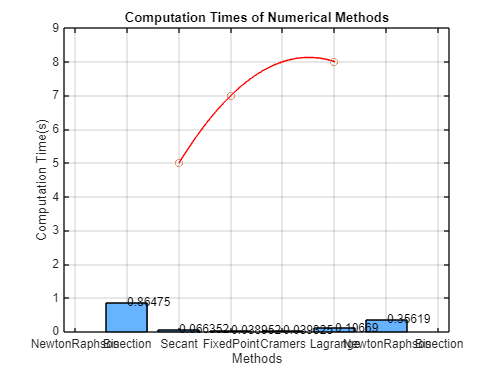


methods = {'NewtonRaphson','Bisection','Secant','FixedPoint','Cramers','Lagrange'};
Computation_times = [0.864748,0.066352,0.038952,0.039325,0.106690,0.356190];
bar(Computation_times,'FaceColor',[0.4 0.7 1]);
set(gca,'XTickLabel',methods);
title('Computation Times of Numerical Methods');
xlabel('Methods');
ylabel('Computation Time(s)');
grid on;
xtips = 1:length(Computation_times);
ytips = Computation_times;
labels = string(Computation_times);
text(xtips,ytips + 0.0002, labels);
box on;